% Parameters for Bangalore Metro Traffic Recovery
arrivalTimes = [300, 420, 240, 360, 480];  % in seconds
departureTimes = [0, 300, 420, 240, 360];  % in seconds
idealTimes = [240, 300, 360, 420, 480];    % in seconds
actualTimes = [300, 420, 480, 540, 600];   % in seconds
distances = [2000, 2000, 2500, 3000, 1500]; % in meters
speeds = [8.33, 8.33, 6.94, 5.56, 11.11];  % in m/s
gamma = 0.01;                              % Emission factor in kg CO₂ per meter
alpha = 0.05;                              % Fuel coefficient per distance
beta = 0.01;                               % Fuel coefficient per time
delta = 0.02;                              % Emission penalty factor
theta = 0.03;                              % Fuel consumption penalty factor

% Observed data
observedQ = [300, 420, 480, 540, 600];  % Observed travel times (in seconds)
sigma = 30;               % Standard deviation of observed data (in seconds)
lambda = 0.05;            % Regularization parameter

% Additional Parameters (same as DE)
recklessDriving = [1, 0, 1, 0, 0];  % Binary array representing reckless driving instances
railroadDelays = [0, 1, 0, 0, 1];   % Binary array representing railroad delays
signalDelays = [1, 0, 1, 0, 0];     % Binary array representing signal delays
emissions = [0.5, 0.4, 0.3, 0.6, 0.7]; % Emissions for each trip
fuelConsumption = [0.1, 0.15, 0.2, 0.12, 0.1]; % Fuel consumption per trip

% PSO Parameters
numVariables = length(observedQ);
numParticles = 100;  % Increased particles for better exploration
maxIterations = 200; % Increase number of iterations for better convergence
positionRange = [0, 1];  % Position range between 0 and 1

% Initialize positions and velocities
positions = positionRange(1) + (positionRange(2) - positionRange(1)) * rand(numParticles, numVariables);
velocities = zeros(numParticles, numVariables);

% Fitness function for PSO 
fitnessFunction = @(Q) objectiveFunction(Q, observedQ, sigma, lambda, ...
    recklessDriving, railroadDelays, signalDelays, emissions, fuelConsumption, ...
    alpha, beta, gamma, delta, theta, actualTimes, speeds, distances);

% Personal and global best initialization
personalBestPositions = positions;
personalBestFitness = arrayfun(@(i) fitnessFunction(personalBestPositions(i, :)), 1:numParticles);
[globalBestFitness, idxGlobalBest] = min(personalBestFitness);
globalBestPosition = personalBestPositions(idxGlobalBest, :);

% Store best fitness values per iteration
bestFitnessValuesPSO = zeros(maxIterations, 1);
consecutiveSameBestCount = 0;

% Set format for long precision output
format long;

% Start the timer
tic;

% PSO Optimization Loop
for iter = 1:maxIterations
    % Update velocities and positions with a smoother inertia weight
    inertiaWeight = 0.9 - 0.4 * (iter / maxIterations); % Slow down inertia decrease
    r1 = rand(numParticles, numVariables);
    r2 = rand(numParticles, numVariables);
    velocities = inertiaWeight * velocities + 2.0 * r1 .* (personalBestPositions - positions) + 2.0 * r2 .* (globalBestPosition - positions);
    
    % Clamp velocities to avoid exceeding max limits
    velocities = min(max(velocities, -0.1), 0.1);  % Restrict velocity change
    
    positions = min(max(positions + velocities, positionRange(1)), positionRange(2)); % Clamp positions within range
    
    % Calculate fitness and update personal and global bests
    fitnessValues = arrayfun(@(i) fitnessFunction(positions(i, :)), 1:numParticles);
    for i = 1:numParticles
        if fitnessValues(i) < personalBestFitness(i)
            personalBestFitness(i) = fitnessValues(i);
            personalBestPositions(i, :) = positions(i, :);
        end
    end

    [currentBestFitness, idxBest] = min(fitnessValues);
    if currentBestFitness < globalBestFitness
        globalBestFitness = currentBestFitness;
        globalBestPosition = positions(idxBest, :);
        consecutiveSameBestCount = 0;
        
        % Display the best fitness value at each improvement
        fprintf('Iteration %d: Best Fitness = %.5f\n', iter, globalBestFitness);
    else
        consecutiveSameBestCount = consecutiveSameBestCount + 1;
    end
    
    bestFitnessValuesPSO(iter) = globalBestFitness;

    % Early stopping if fitness remains the same for two consecutive iterations
    if consecutiveSameBestCount >= 2
        fprintf('Early stopping at iteration %d.\n', iter);
        break;
    end
end

Iteration 2: Best Fitness = 0.24779
Iteration 3: Best Fitness = 0.24502
Iteration 4: Best Fitness = 0.24159
Iteration 5: Best Fitness = 0.24013
Iteration 6: Best Fitness = 0.23983


Early stopping at iteration 8.



% Stop the timer and display runtime
totalTimePSO = toc;
fprintf('Total Runtime for PSO: %.2f seconds\n', totalTimePSO);

Total Runtime for PSO: 0.02 seconds


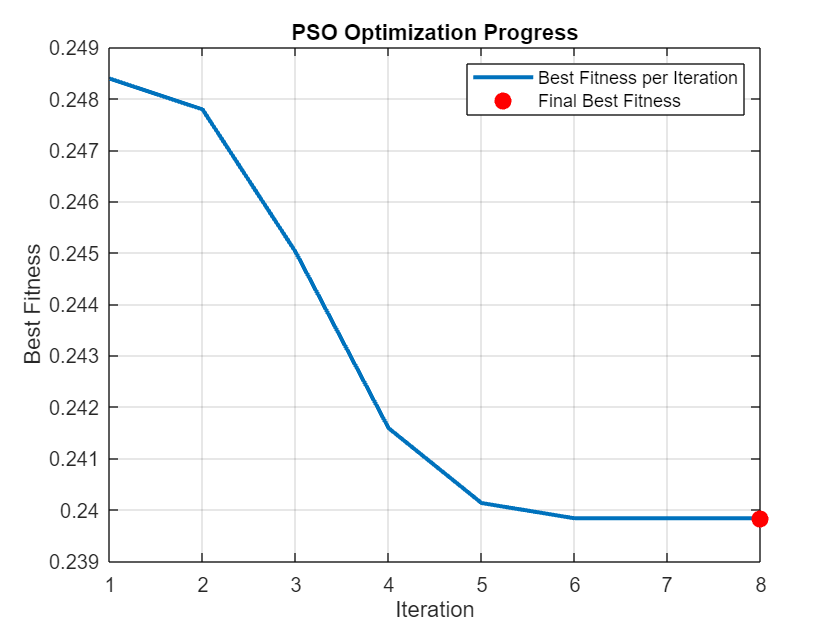


% Plotting PSO Optimization Progress
figure;
plot(1:iter, bestFitnessValuesPSO(1:iter), 'LineWidth', 2);
hold on;
plot(iter, globalBestFitness, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
xlabel('Iteration');
ylabel('Best Fitness');
title('PSO Optimization Progress');
grid on;
legend('Best Fitness per Iteration', 'Final Best Fitness');
hold off;


% Objective function for PSO


function F = objectiveFunction(Q, observedQ, sigma, lambda, RD, RC, S, E, Fcons, alpha, beta, gamma, delta, theta, actualTimes, speeds, distances)
    % Compute penalties
    discrepancyTerm = 0;
    for i = 1:length(Q)
        % Calculate discrepancy based on delta(t_i) - (t_i * v_i) / s_i
        discrepancyTerm = discrepancyTerm + (delta - ((actualTimes(i) * speeds(i)) / distances(i)) - Q(i))^2;
    end
    discrepancyTerm = discrepancyTerm / sigma^2;
    
    % Regularization term
    regularizationTerm = lambda * norm(Q, 2)^2;
    
    % Penalties
    recklessDrivingPenalty = alpha * sum(RD);
    railroadDelayPenalty = beta * sum(RC);
    signalDelayPenalty = gamma * sum(S);
    emissionPenalty = delta * sum(E);
    fuelPenalty = theta * sum(Fcons);
    
    % Combine terms into the final objective function
    F = 1 * (discrepancyTerm + regularizationTerm + recklessDrivingPenalty ...
        + railroadDelayPenalty + signalDelayPenalty + emissionPenalty + fuelPenalty);
end
